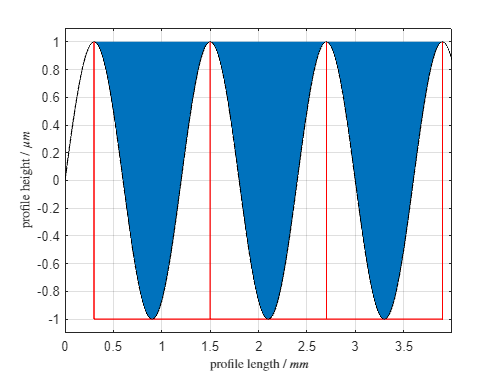

clc;clear;close all;
format long
dx = 0.5;
load("profile\simple_sin_1_open_peak.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z, dx, M);


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDhm_theo = 2;
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDwm_theo = 1200;
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x)=sin(2*pi*x/1200);
HDvm_theo = double(int(f(x)+1, 300, 1500)/(length(z)*dx));
HDlm = feature_parameter(z, dx, M, "All", 1, "HDl", "Mean");
l = int(sqrt(1+diff(f(x),x)^2),[300 1500]);
HDlm_theo = double(l);
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean");
k(x) = diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(900));
% output table
T(1) = struct('parameter',"Mean motif height",'Feature_Characterization',HDhm,'theoretical_value',HDhm_theo);
T(2) = struct('parameter',"Mean motif width",'Feature_Characterization',HDwm,'theoretical_value',HDwm_theo);
T(3) = struct('parameter',"Mean motif volume",'Feature_Characterization',HDvm,'theoretical_value',HDvm_theo);
T(4) = struct('parameter',"Mean motif dev. length",'Feature_Characterization',HDlm,'theoretical_value',HDlm_theo);
T(5) = struct('parameter',"Mean motif pit curvature",'Feature_Characterization',Rmvc,'theoretical_value',Rmvc_theo);
T

T = 1×5 struct array with fields:
    parameter
    Feature_Characterization
    theoretical_value


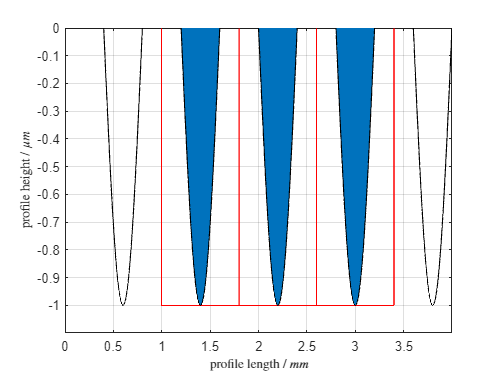


load("profile\sinus_04_zeros_04.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);

HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x)=sin(2*pi*x/800);
HDvm_theo = abs(double(int(f(x), 400, 800)/((length(z)-1)*dx)));
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean");
Rmpc = feature_characterization(z, dx, "P", "Wolfprune 0.1", "All", "Curvature", "Mean");

% Pits are plateaus with 2 points with same height!
syms x
f(x)=sin(2*pi*x/800);
k(x)=diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(600));

T(1) = struct('parameter',"Mean motif height",'Feature_Characterization',HDhm,'theoretical_value',1);
T(2) = struct('parameter',"Mean motif width",'Feature_Characterization',HDwm,'theoretical_value',HDwm_theo);
T(3) = struct('parameter',"Mean motif volume",'Feature_Characterization',HDvm,'theoretical_value',HDvm_theo);
T(4) = struct('parameter',"Mean motif dev. length",'Feature_Characterization',HDlm,'theoretical_value',HDlm_theo);
T(5) = struct('parameter',"Mean motif pit curvature",'Feature_Characterization',Rmvc,'theoretical_value',Rmvc_theo);
T(6) = struct('parameter',"Mean motif peak curvature",'Feature_Characterization',Rmpc,'theoretical_value',0);
T

T = 1×6 struct array with fields:
    parameter
    Feature_Characterization
    theoretical_value


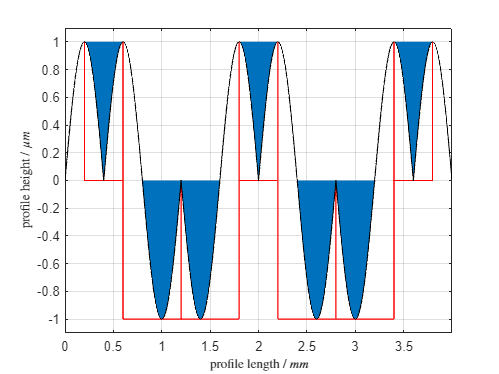


load("profile\kuppen_taeler_4mm.mat")
figure
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);

HDvx = feature_parameter(z, dx, M, "All", 1, "HDv", "Max")

HDvx =    0.063661895424428


syms x
f(x)=-sin(2*pi*x/800);
HDvm_theo = double(int(f(x), 0, 400))

HDvm_theo =     -2.546479089470325e+02


HDvmin = feature_parameter(z, dx, M, "All", 1, "HDv", "Min")

HDvmin =    0.036338104575572


HDvm_theo = 2*double(int(f(x)+1, 0, 200))

HDvm_theo =      1.453520910529675e+02


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =      1


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =    400


Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =    0.016640788992974


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =    0.016640788992974


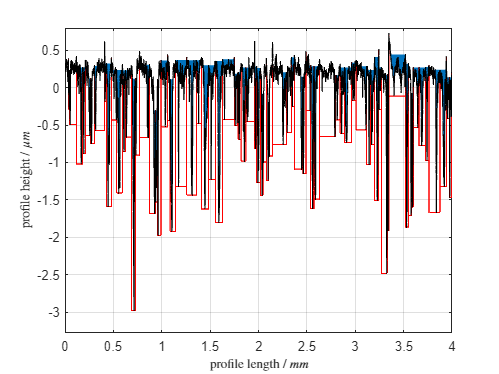


load("profile\Luftpresser_1_56_ak.mat")
M = watershed_segmentation(z, dx, "D","Wolfprune", 0.5);
figure
plot_motifs(z,dx,M);

HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")

HDvm =    0.003491995008230


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =    1.207708311259053


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =   48.210499291321511


Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =    0.500325534971493


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =    0.500325534971493


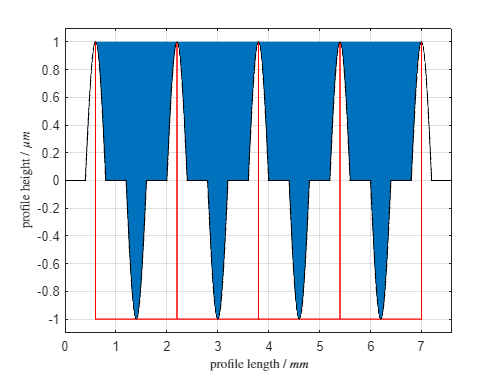


load("profile\zeros_kuppen_taeler.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);

HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")

HDvm =    0.210526315789474


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =      2


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =         1600


Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =      6.168502750856971e-05


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =      6.168502750856971e-05


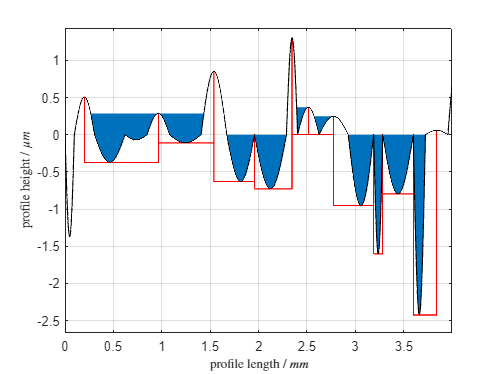


load("profile\tstRSm_random.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);

HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")

HDvm =    0.032603293382449


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =    0.880425779433305


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =      2.908366530613615e+02


Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =    0.021971565275136


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =    0.021971565275136


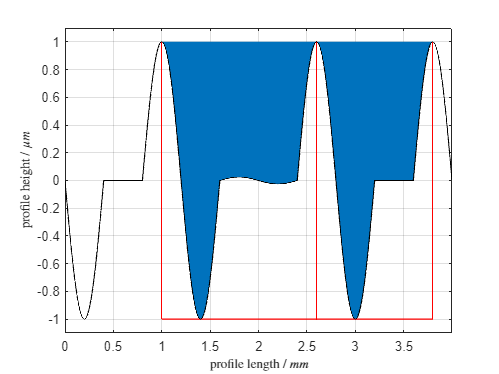


load("profile\sinus_04_sinus_04.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);

HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")

HDvm =    0.350000000000000


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =      2


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =         1400


Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =      6.168502750856971e-05


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =      6.168502750856971e-05


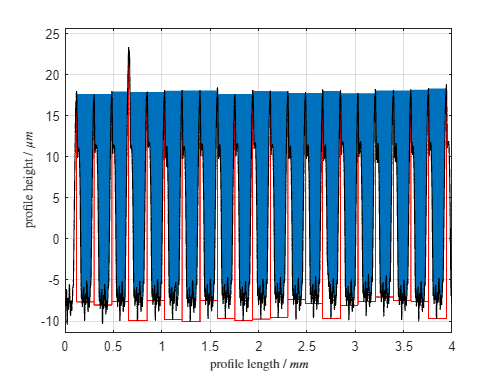


load("profile\Bu_1_56_ak.mat")
M = watershed_segmentation(z,dx,"D","Width","opt");
figure
plot_motifs(z,dx,M);

HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")

HDvm =    0.811478908250985


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")

HDhm =   26.461823860088231


HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")

HDwm =      1.796823947653583e+02


RSm = 182; % 
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmpc =    0.474954581453708


Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

Rmvc =    0.474954581453708
